# Figure 3. Biophysical forward modeling

clear
clc

## load data

% load session average iCSDs
load('sw_hemi_icsd.mat')

% load V4 lead field matrix
load('lead_fields\leadFieldDipBEMVert29909_Plg142V4Dip.mat', 'Ke')

## compute the grand avg CSD

iCSD_contra_gavg = mean(icsd_contra, 3, 'omitnan');
iCSD_ipsi_gavg = mean(icsd_ipsi, 3, 'omitnan');

## plot CSD maps

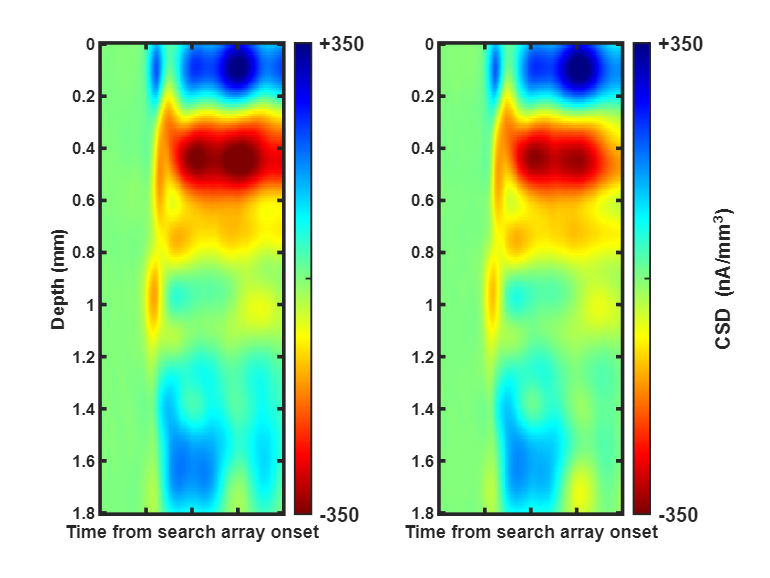

tspan = -50:200;
font = 9;

figure;
subplot(1,2,1)
imagesc(tspan, icsd_pos, iCSD_contra_gavg);
c = colorbar;
colormap(flip(jet));
% c.Label.String = {'CSD', 'nA/mm^{3}'};
bar_min = -350;
bar_max = 350;
caxis([bar_min bar_max]);
c.Label.FontSize = font+2;
c.FontSize = font+2;
c.FontWeight = 'bold';
c.Ticks = [-350 0 350];
c.TickLabels = {'-350', '', '+350'};
c.LineWidth = 1;
ax = gca;
ax.FontSize = font;
xticks([0 50 100 150 200])
xticklabels({})
xlim([0 200])
ylabel('Depth (mm)')
xlabel('Time from search array onset')
set(ax,'fontweight','bold','FontSize',9,'LineWidth',2)

subplot(1,2,2)
imagesc(tspan, icsd_pos, iCSD_ipsi_gavg);
c = colorbar;
colormap(flip(jet));
c.Label.String = 'CSD (nA/mm^{3})';
max_CSD = max(abs(iCSD_contra_gavg), [], 'all');
caxis([bar_min bar_max]);
c.Label.FontSize = font+2;
c.FontSize = font+2;
c.FontWeight = 'bold';
c.Ticks = [-350 0 350];
c.TickLabels = {'-350', '', '+350'};
c.LineWidth = 1;
% c.Position = [0.81 0.1 0.02 0.2];
ax = gca;
ax.FontSize = font;
xticks([0 50 100 150 200])
xticklabels({})
xlim([0 200])
xlabel('Time from search array onset')
set(ax,'fontweight','bold','FontSize',9,'LineWidth',2)

## calculate the dipole moment from grand avg CSDs

rc = 3/2;
d_iCSDcontra = cal_dip_CSD(icsd_pos, iCSD_contra_gavg, rc); % nA*m
d_iCSDipsi = cal_dip_CSD(icsd_pos, iCSD_ipsi_gavg, rc); % nA*m

file = 'NeuroImage_FMoutput';
if ~isfolder(file) % checks if the folder already exists
    mkdir(file);  % creates a folder named 'file'
end
save(fullfile(file, 'Plg142V4Dip_sess_avg.mat'), 'd_iCSDipsi', ...
    'd_iCSDcontra')

## plot dipole moments - Fig3B

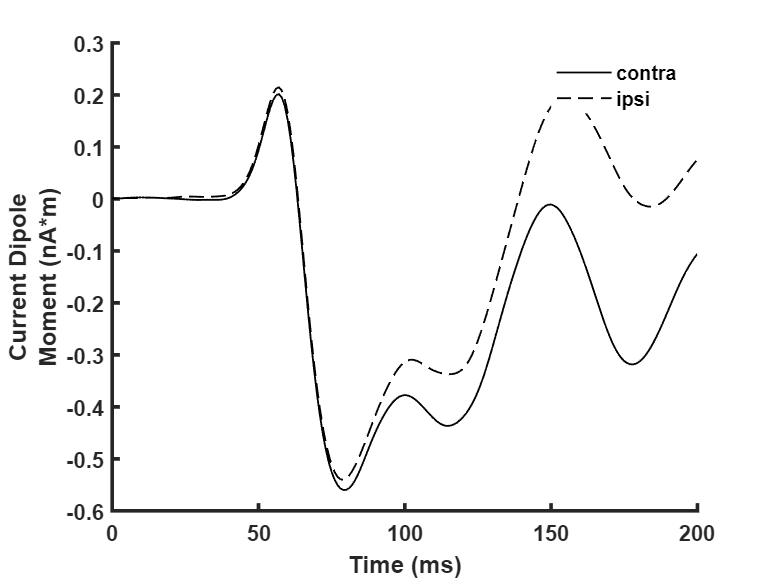

figure;
plot(tspan, d_iCSDcontra, '-k','LineWidth',1)
hold on;
plot(tspan, d_iCSDipsi, '--k','LineWidth',1)
ylabel({'Current Dipole','Moment (nA*m)'})
xlabel('Time (ms)')
xlim([0 200])
legend({'contra','ipsi'},'Box','off')
box off
set(gca,'fontweight','bold','FontSize',12,'LineWidth',2)

## calculate EEG for a target inside the RF (attended), and target opposite RF (unattended)

d_attended = [d_iCSDcontra; d_iCSDipsi].*1e-3; % uA*m
d_unattended = [d_iCSDipsi; d_iCSDcontra].*1e-3; % uA*m
EEG_attended = Ke*d_attended; % uV
EEG_unattended = Ke*d_unattended; % uV

% %% plot EEGs 2D
% 
% figure;
% subplot(2,1,1)
% plot(tspan, EEG_attended')
% title('Attended')
% xticks({})
% xlim([0 200])
% set(gca,'fontweight','bold','FontSize',10,'LineWidth',2)
% 
% subplot(2,1,2)
% plot(tspan, EEG_unattended')
% title('Attended')
% xlim([0 200])
% xlabel('Time from search array onset')
% set(gca,'fontweight','bold','FontSize',10,'LineWidth',2)